# Main con repulsive potentials

Configuration space

clear; close all; clc;
grid = Grid(2,0,10);
grid.setGoal([10,10]);

Obstacles and robot initial configuration

grid.addObstacle(Obstacle(3.5,6,[0;0]));
grid.addObstacle(Obstacle(5,4,[0;0]));
n = length(grid.obstacles);
r = Robot(2,2);

Attractive potential

fatt = 1/2*( (grid.X - grid.goal(1)).^2 + (grid.Y - grid.goal(2)).^2 );
agradX = grid.goal(1)-grid.X; agradY = grid.goal(2)-grid.Y;

Repulsive potential

rgradX = zeros(grid.nc); rgradY = zeros(grid.nc); frep = zeros(grid.nc);
for i = 1 : n
    %Distanza rispetto agli ostacoli
    dx = abs(grid.X - grid.obstacles(i).xc);
    dy = abs(grid.Y - grid.obstacles(i).yc);
    d = sqrt(dx.^2 + dy.^2);
    %Potenziale
    freptemp = 1/2*((1./d - 1/2).^2);
    freptemp(d > 2) = 0;
    freptemp(isinf(freptemp)) = 10;
    frep = frep + freptemp;
    %Antigradiente
    [rgradXtemp, rgradYtemp] = gradient(-frep,1/1000);
    %Lo sommo ai precedenti
    rgradX = rgradX + rgradXtemp;
    rgradY = rgradY + rgradYtemp;
end

Total potential

gradX = rgradX + agradX; 
gradY = rgradY + agradY;
potential = frep + fatt;
quiver(grid.X,grid.Y,gradX,gradY); hold on;
% mesh(potential); view([-122.4 43.8]); hold on;
% frame = getframe(gcf);

Modules declaration

act = Act(r,grid);

Simulation

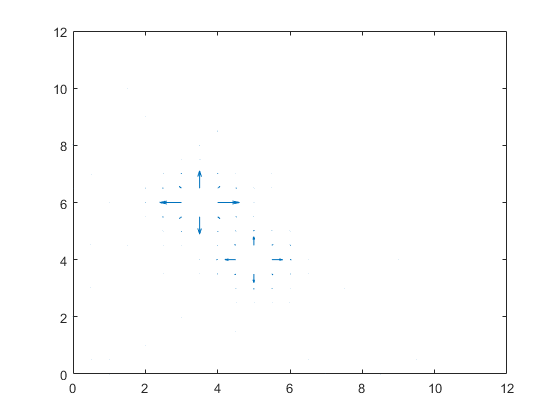

e = norm([r.xc,r.yc]-grid.goal); 
global tspan; tspan = 0.01;
global tsim; tsim = 0;
path = [];
while(e > 0.1 && tsim < 5)
    rx = r.xc; ry = r.yc;
    rp = grid.coord2index([rx,ry]);
    z = potential(rp(1),rp(2));
    path = [path ; rp(2) rp(1) z];
    act.move(gradX,gradY);
    e = norm([rx,ry]-grid.goal);
    tsim = tsim + tspan; pause(0);
    r.draw(true);
end

% scatter3(path(:,1),path(:,2),path(:,3),"filled","linewidth",3);